# **IO135 - Analog and Digital Loopback**

The IO135 I/O module is a fast, simultaneous-sampling, 16-bit analog input and output module, with additional individually configurable TTL digital I/O lines.

This example demonstrates a simple communication between the two Analog inputs and outputs present on the IO135, without using DMA (Direct Memory Access), as well as the communication between two DIO pins.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO135 I/O module installed

- Connector cable from the I/O module to the terminal boards

- 2 50-pin terminal boards with jumper wires

### Test Setup

On the terminal board of the analog I/O module, connect the positive (+) pins of Analog Inputs 1 and 2 to the pins of Analog Outputs 1 and 2, and connect the negative (-) pins of Analog Inputs 1 and 2 to GND. Finally, connect DIO 1 and DIO 5.

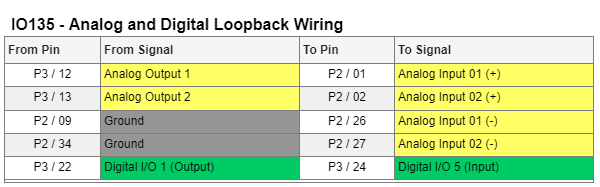

[IO135 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO135_Loopback';
open_system(modelName);

### Model Description

The Simulink model features the [IO135 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_setup_v2), [IO135 Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_analog_input_v2), [IO135 Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_analog_output_v2), [IO135 Digital Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_digital_input_v2) and [IO135 Digital Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_digital_input_v2) blocks. Analog Inputs and Outputs 1 and 2 as well as Digital Inputs and Outputs 1 and 5 are enabled in the Setup Block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

By clicking on the scope after the model has terminated, you should be able to see the input signal of both channels.

If you wish to sample a signal with a sample rate higher than the fundamental sample time of the Simulink model, consider using DMA, a concept that is featured in another example for the IO135. 

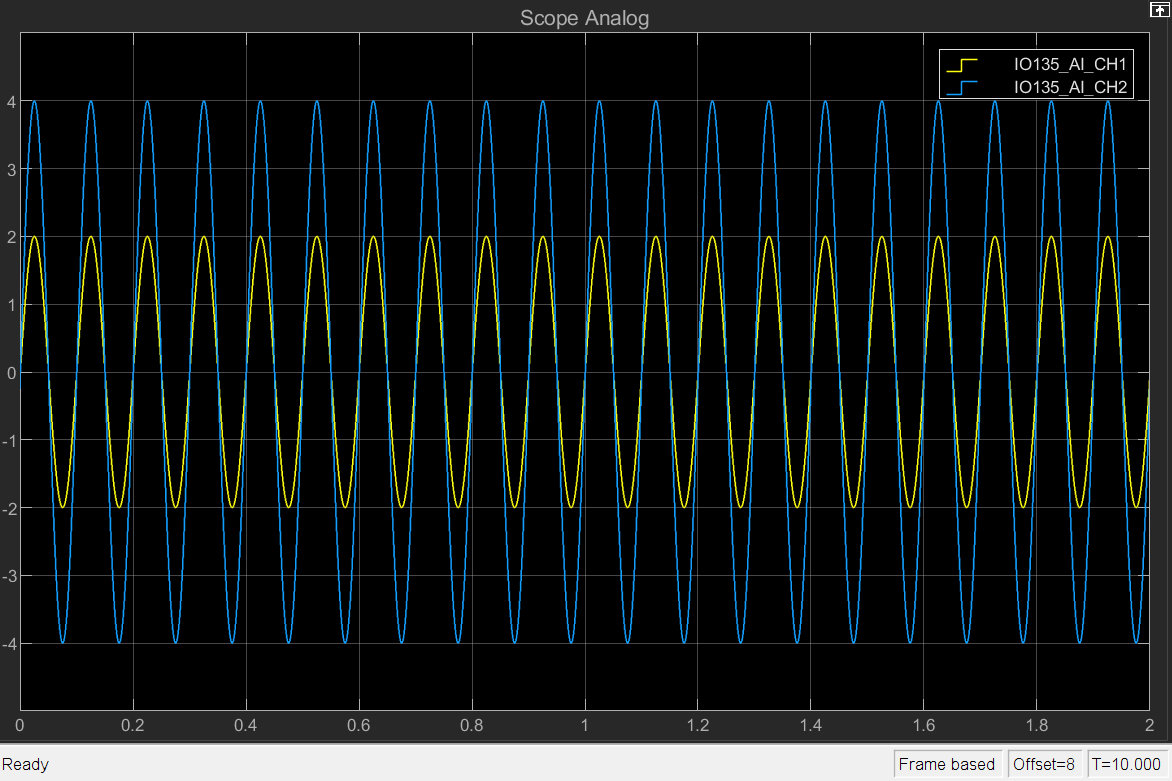

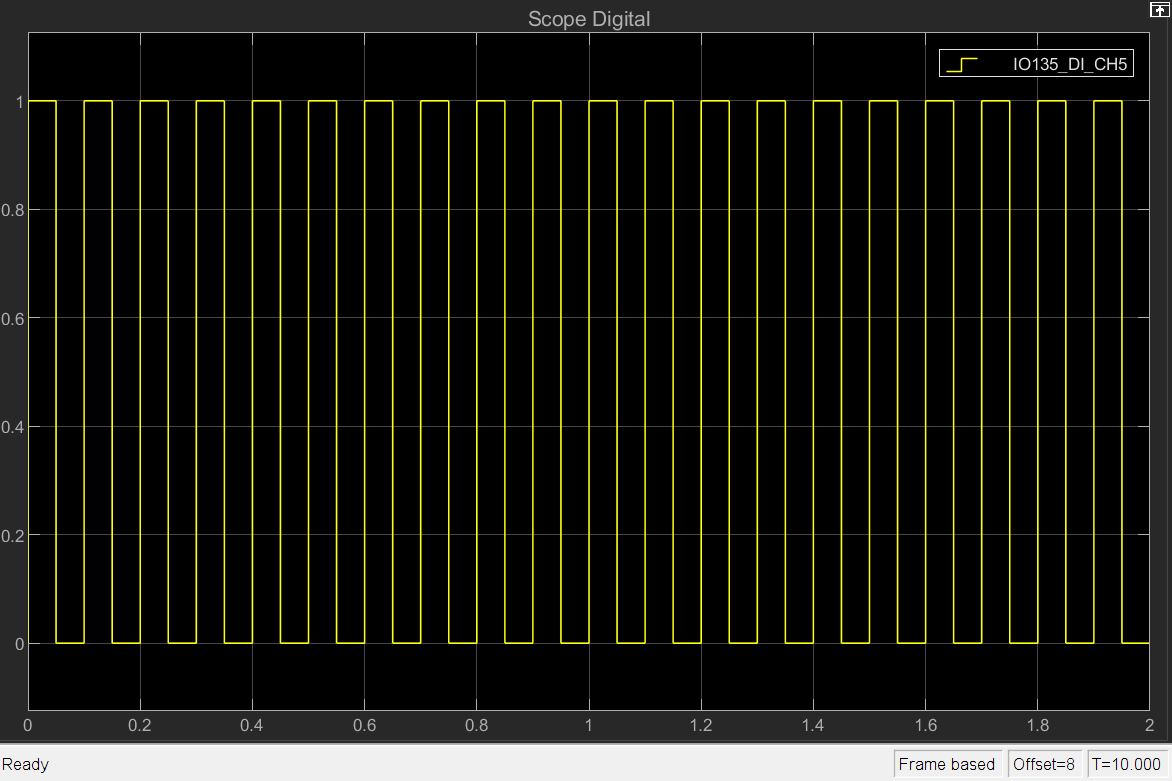

## Additional References

- [IO135 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io135)